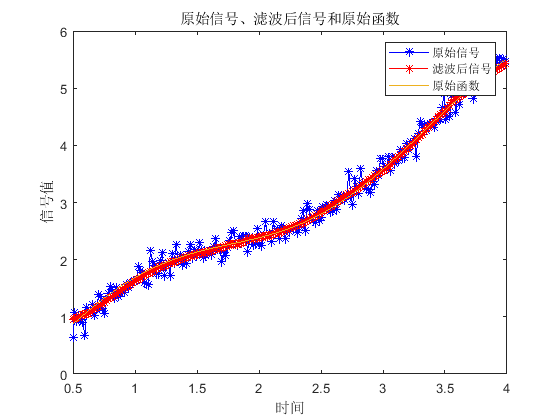

clc
clear 
close all

% 生成随机参数
a = (1.045 - 0.780) * rand() + 0.780;
omega = (2 - 1.884) * rand() + 1.884;
phi = 2 * pi * rand(1, 1);

% 生成随机信号函数
fn = @(t) -a ./ omega * cos(omega * t + phi) + (2.090 - a) * t;

% 采样时间步长
dt = 0.016;
t0 = 0.5:dt:4;

% 添加噪声
theta = mod(fn(t0) + 0.04 * pi * randn(1, length(t0)), 2 * pi);


% 使用smoothdata函数进行均值滤波
window_size = 20; % 窗口大小
smoothed_theta = smoothdata(theta, 'movmean', window_size, 'omitnan');
% 绘制原始信号、滤波后的信号和原始函数
plot(t0, theta, "b*-", t0, smoothed_theta, "r*-", t0, fn(t0))
title('原始信号、滤波后信号和原始函数');
xlabel('时间');
ylabel('信号值');
legend('原始信号', '滤波后信号', '原始函数');

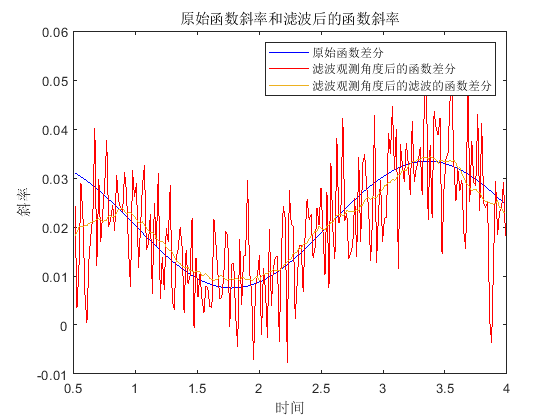


% 计算预测的函数斜率
dtheta = diff(smoothed_theta);
no_dtheta = diff(fn(t0));
window_size = 30;
smoothed_dtheta = smoothdata(dtheta, 'movmean', window_size, 'omitnan');

% 绘制预测的函数斜率（未滤波和滤波后）
figure;
plot(t0(2:end), no_dtheta, 'b', t0(2:end), dtheta, 'r', t0(2:end), smoothed_dtheta);
title('原始函数斜率和滤波后的函数斜率');
xlabel('时间');
ylabel('斜率');
legend('原始函数差分', '滤波观测角度后的函数差分','滤波观测角度后的滤波的函数差分');